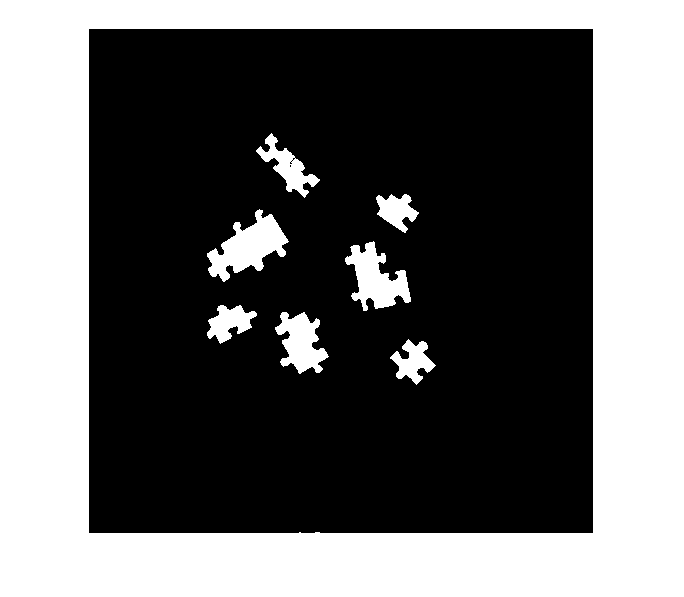

img = imread("Puzzle_01.jpg");
X = rgb2gray(img);
% Threshold image - adaptive threshold
BW = imbinarize(X, 'adaptive', 'Sensitivity', 0.500000, 'ForegroundPolarity', 'bright');

% Open mask with disk
radius = 1;
decomposition = 0;
se = strel('disk', radius, decomposition);
BW = imopen(BW, se);

% Fill holes
BW = imfill(BW, 'holes');

% Open mask with disk
radius = 2;
decomposition = 0;
se = strel('disk', radius, decomposition);
BW = imopen(BW, se);
imshow(BW)

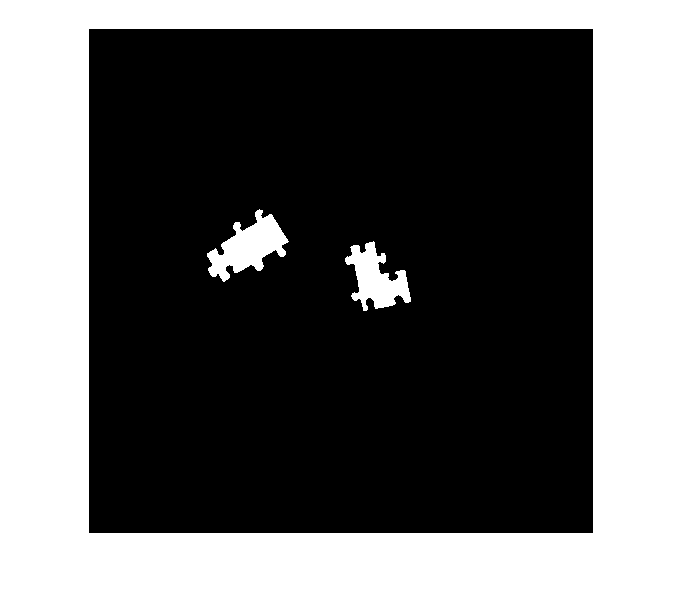

[bw_out,properties] = filterRegionsPuzzle_01(BW);
imshow(bw_out)

properties2 = regionprops("table",bw_out,"BoundingBox")

properties2 = 2×1 table
              BoundingBox           
    ________________________________

    352.5    541.5      248      219
    769.5    637.5      198      210


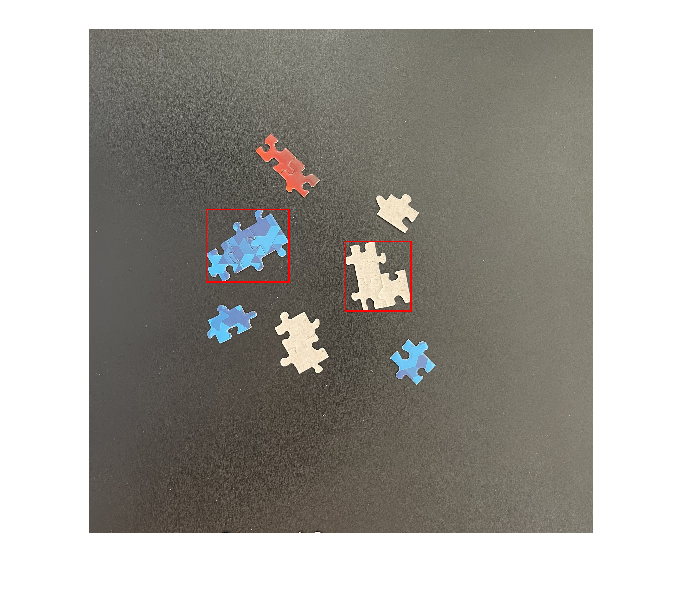

img2 = insertShape(img,"Rectangle",properties2.BoundingBox,"color","red","LineWidth",5);
imshow(img2)